#### Microsoft Call Option Outcomes with Expected Rise

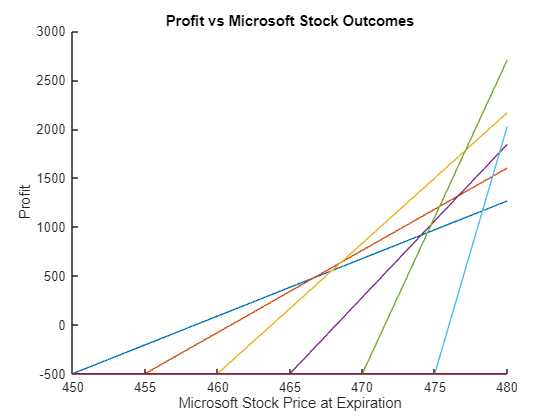

Microsoft_Outcomes = 450:.01:480;

Option_Strikes = [450 455 460 465 470 475 480];
Option_Prices = [8.5 5.95 3.75 3.2 1.56 .99 .6];

Option_Outcomes = nan(length(Option_Prices),length(Microsoft_Outcomes));

figure
hold on
for row_index = 1:length(Option_Prices)
    num_options = 500/Option_Prices(row_index); % Assume that we only spend $500 on Options
    Option_Outcomes(row_index,:) = max(Microsoft_Outcomes-Option_Strikes(row_index),0) - Option_Prices(row_index);
    plot(Microsoft_Outcomes,num_options*Option_Outcomes(row_index,:))
end
xlabel('Microsoft Stock Price at Expiration')
ylabel('Profit')
title('Profit vs Microsoft Stock Outcomes')

#### Expected Value Based Analysis

% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?

test_mu = .05;
test_sigma = .31;
[~,open_prices] = geometric_brownian_motion(100,1,1e4,test_mu,test_sigma);
clear("stock_data")
stock_data(length(open_prices)) = struct();
for index = 1:length(open_prices)
    stock_data(index).Open = open_prices(index);
end
test_black_scholes_params = estimate_black_scholes_parameters(stock_data,'Open',1)

test_black_scholes_params = struct with fields:
           best_mu: 0.1039
        best_sigma: 0.3142
       mu_interval: [0.0027 0.1767]
    sigma_interval: [0.3100 0.3182]






filename = "C:\Users\wynga\OneDrive\Desktop\PhD_Research\Options Trading\Stock Data\MSFT.csv";
stock_data = read_yahoo_finance_csv(filename);


black_scholes_params = estimate_black_scholes_parameters(stock_data,'Open',1)

black_scholes_params = struct with fields:
           best_mu: 0.0905
        best_sigma: 0.2135
       mu_interval: [0.0093 0.1499]
    sigma_interval: [0.2005 0.2324]


% Historic Volatility for the year is approximately 21.3
% https://marketchameleon.com/Overview/MSFT/IV/

% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?




spot_price = 449.15;
mu = black_scholes_params.best_mu;
sigma = black_scholes_params.best_sigma;
time_to_expiration = 19/365;
option_type = 'Call';
option_price = 5.95;
strike_price = 455;
max_price = 600;

[expected_value,variance] = black_scholes_expected_value(spot_price,mu,sigma,time_to_expiration,...
                            option_type,option_price,strike_price,'max_price',max_price)

expected_value = 1.6001

variance = 152.1089

standard_deviation = sqrt(variance)

standard_deviation = 12.3332


% Check:
% Does Numerical runs of Expected Value with generated
% Geometric_Brownian_Motion match expected?





% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?

% Does Numerical runs of Expected Value with generated
% Geometric_Brownian_Motion match expected?
